clear all

f=@(x)exp(-(x-10).^2).*cos(6*(x-10))

f = function_handle with value:
    @(x)exp(-(x-10).^2).*cos(6*(x-10))


df=@(x)-2.*(x-10).*exp(-(x-10).^2).*cos(6*(x-10))-6.*exp(-(x-10).^2).*sin(6*(x-10))

df = function_handle with value:
    @(x)-2.*(x-10).*exp(-(x-10).^2).*cos(6*(x-10))-6.*exp(-(x-10).^2).*sin(6*(x-10))


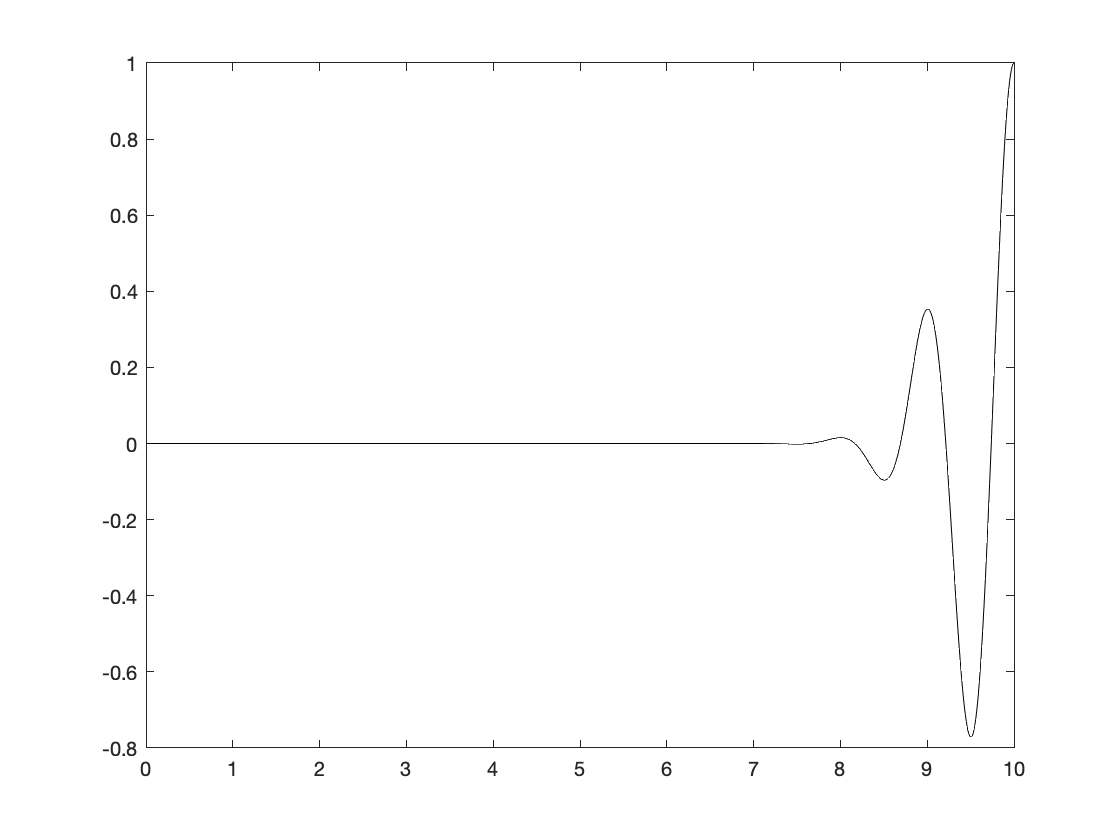

xveryfine=linspace(0,10,1000);

plot(xveryfine,f(xveryfine),'k-')

n=100;
xi=linspace(0,10,n);
fi=f(xi);
Delta=xi(2)-xi(1);

Creating the derivative matrix

b=zeros(n,1);
b(1)=-1;
b(end)=1;

a=-0.5*ones(n-1,1);
a(end)=-1;

c=0.5*ones(n-1,1);
c(1)=1;
Deriv=(diag(a,-1)+diag(b)+diag(c,1))/Delta;
dfi=Deriv*fi';

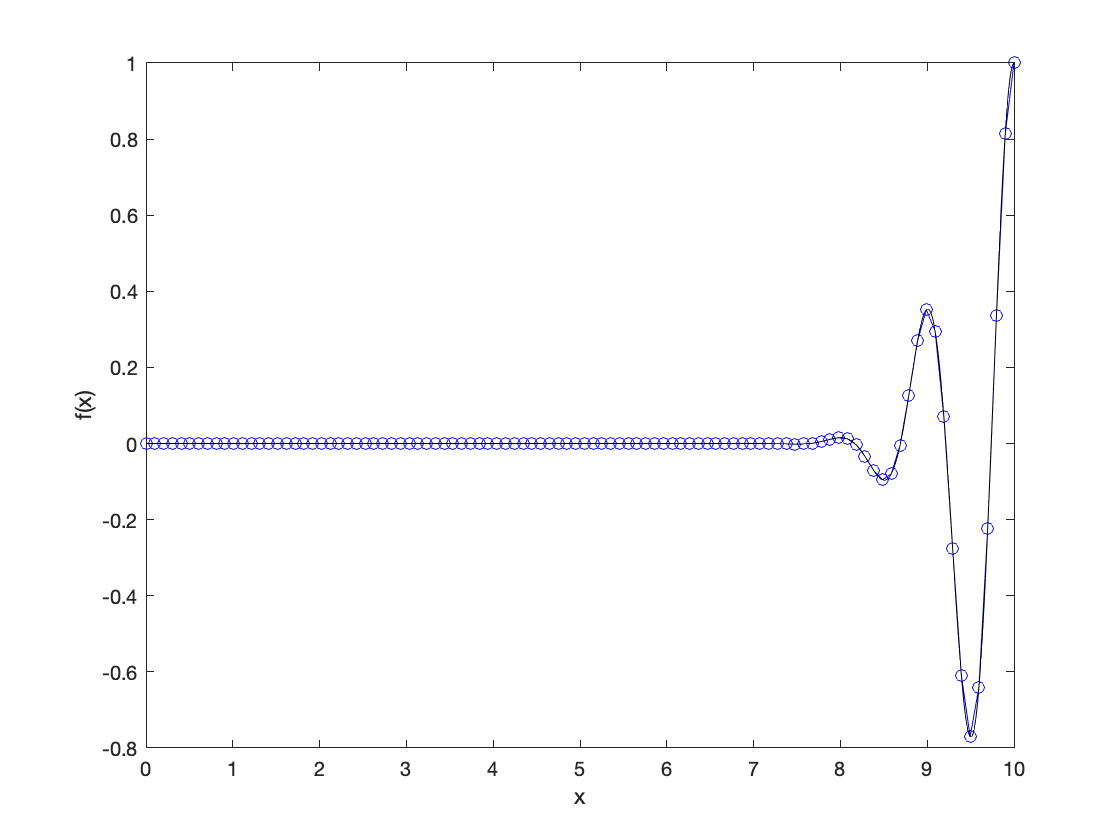

plot(xi,fi,'bo-',xveryfine,f(xveryfine),'k-')
xlabel('x');ylabel('f(x)')

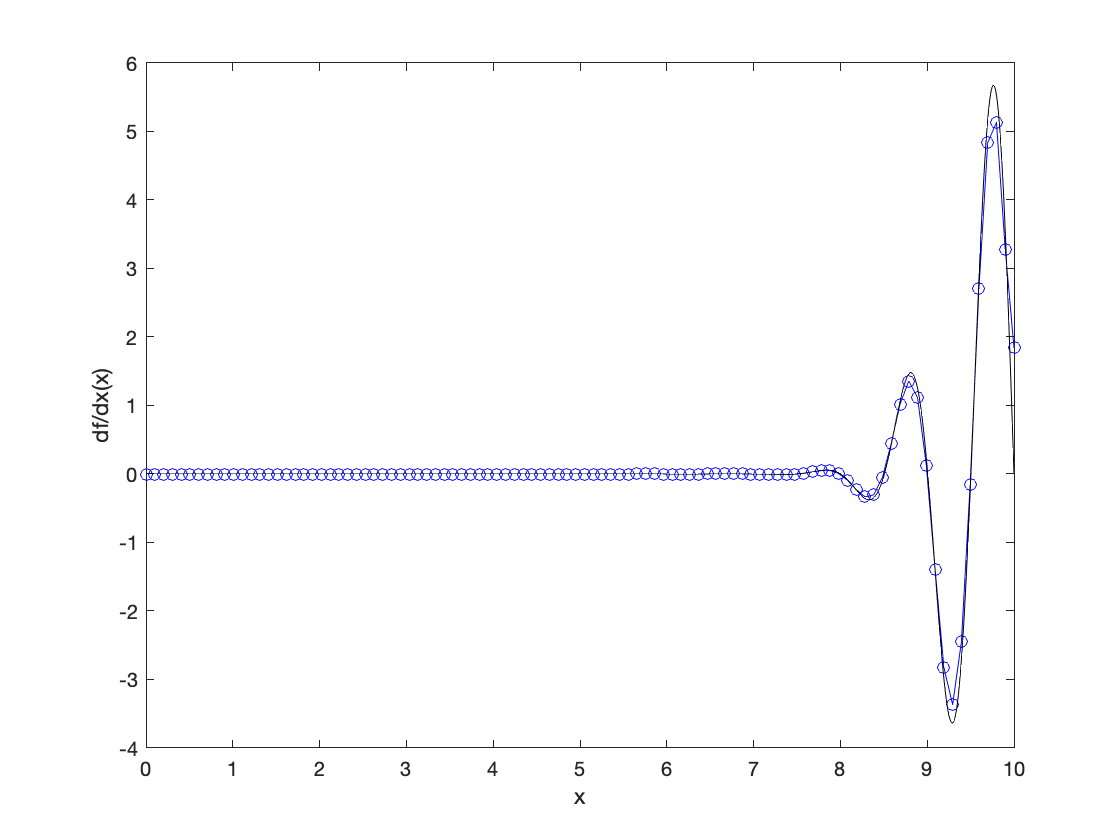


plot(xi,dfi,'bo-',xveryfine,df(xveryfine),'k-')
xlabel('x');ylabel('df/dx(x)')